# Machine learning with MPS

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr)

Here we demonstrate how the MPS technology can be used in machine learning, with the application to handwriting recognition. We implement the algorithm introduced in Stoudenmire2016 [[E. M. Stoudenmire and D. J. Schwab, Adv. Neural Inf. Process. Syst. **29**, 4799 (2016)](https://proceedings.neurips.cc/paper/2016/file/5314b9674c86e3f9d1ba25ef9bb32895-Paper.pdf) or [its arXiv version](https://arxiv.org/abs/1605.05775)]. (Two versions of the paper have minor differences; here we follow the notation of the published NeurIPS version.) The goal of this algorithm is to construct the MPS such that the contraction of the "weight" MPS and feature vectors evaluates how the input data is close to the data pattern with a certain label.

## MNIST data

First, we load the MNIST data of handwritten digits, from the .csv files contained in the same sub-directory with this document. In these .csv files, each row corresponds one handwritten digit. The first column indicates the correct labels. The rest of columns, of column indices `(1:(28^2))+1`, indicate the gray-scale values (from black 0 to white 255) of 28 $\times$ 28 image pixels. For each row, the `(2:(28^2+1))` elements are the concatenation of rows of an image, i.e., `[(the_1st_row), (the_2nd_row), ...]`.

For quicker demonstration, we use only a subset for training (i.e., optimizing the MPS) and a smaller subset for test the performance of the trained MPS. (To have better classification result, one needs to use the whole dataset; but it will take more computational cost.)

clear

Ntrain = 2000; % number of training datasets
Ntest = 100; % number of test datasets for verification
Npixel = 28; % number of pixels of an image for each direction

data_train = readmatrix('MNIST_train.csv','Range',[1 1 Ntrain 28^2+1]);
data_test  = readmatrix('MNIST_test.csv', 'Range',[1 1 Ntest  28^2+1]);

The numbers are from 0 to 9.

labels = unique(data_train(:,1));
disp(labels.');

     0     1     2     3     4     5     6     7     8     9



Let's visualize the data.

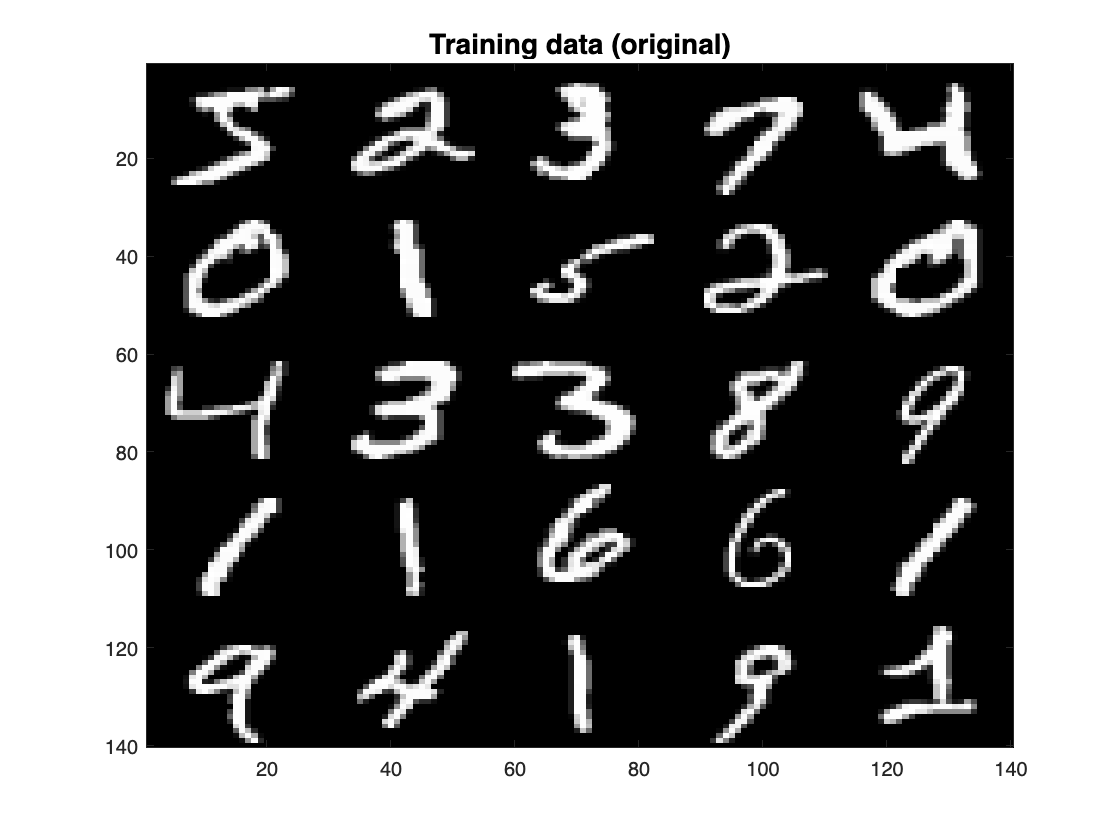

Nshow = [5 5]; % 5-by-5 layout
figure;
imagesc(reshape(permute(reshape(data_train(1:prod(Nshow),2:end), ...
    [Nshow Npixel Npixel]),[4 1 3 2]),Nshow*Npixel));
% permute the dimensions of column/row of pixels for visualization, since
% MATLAB is column-major language
colormap(gray);
title('Training data (original)','FontSize',14);

These gray-scale images are labeled as:

disp(reshape(data_train(1:prod(Nshow),1),Nshow))

     5     2     3     7     4
     0     1     5     2     0
     4     3     3     8     9
     1     1     6     6     1
     9     4     1     9     1



In Stoudenmire2016, the images are down-scaled by factor 2. By down-scaling, we later can use shorter MPS of length $(28/2)^2 = 196$.

data_train = [data_train(:,1), ...
    reshape(mean(mean( ...
    reshape(data_train(:,(2:end)),[size(data_train,1) 2 Npixel/2 2 Npixel/2]), ...
    2),4),[size(data_train,1) (Npixel/2)^2])];
data_test = [data_test(:,1), ...
    reshape(mean(mean( ...
    reshape(data_test(:,(2:end)),[size(data_test,1) 2 Npixel/2 2 Npixel/2]), ...
    2),4),[size(data_test,1) (Npixel/2)^2])];

The down-scaled images look like:

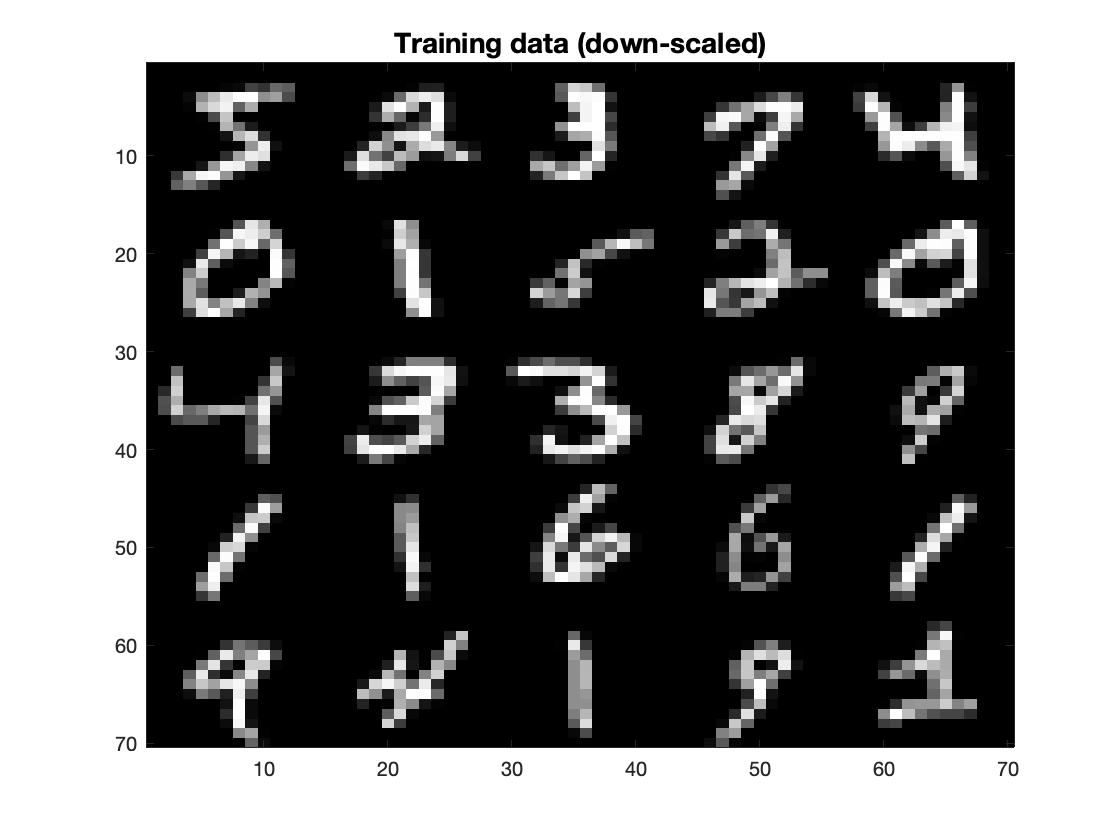

figure;
imagesc(reshape(permute(reshape(data_train(1:prod(Nshow),2:end), ...
    [Nshow Npixel/2 Npixel/2]),[4 1 3 2]),Nshow*Npixel/2));
% permute the dimensions of column/row of pixels for visualization, since
% MATLAB is column-major language
colormap(gray);
title('Training data (down-scaled)','FontSize',14);

## Generate feature vectors and correct decision function

Then the gray-scale pixels are individually mapped onto two-dimensional vectors which are similar to the spin-1/2 spinors. In the machine learning context, we will call such vectors as feature vectors.

We define the mapping from an integer $\in [0, 255]$ to a two-dimensional vector so that for completely white pixels, the vector would be [0 1] and for completely black pixels, [1 0]. We use Eq. (3) of Stoudenmire2016, which provides the one-to-one correspondence between a pixel value and a vector.

dtmp = data_train(:,2:end)*(pi/2/255);
F_train = permute(cat(3,cos(dtmp),sin(dtmp)),[1 3 2]);
% F_train(m,:,n) is the 2-dimensional feature vector for the n-th pixel (=
% site) and the m-th image

% similarly for test data
dtmp = data_test(:,2:end)*(pi/2/255);
F_test = permute(cat(3,cos(dtmp),sin(dtmp)),[1 3 2]);

And we also construct the matrix for correct decision function.

% for training data
y_train = accumarray([(1:size(data_train,1)).', data_train(:,1)+1], ...
    ones(size(data_train,1),1),[size(data_train,1) numel(labels)]);
% y_train(m,n) is 1 if the m-th data (i.e. image) is labeled by the n-th 
% label, 0 otherwise.

% similarly for test data
y_test = accumarray([(1:size(data_test,1)).', data_test(:,1)+1], ...
    ones(size(data_test,1),1),[size(data_test,1) numel(labels)]);

## Exercise (a): Complete the function for the MPS-based machine learning method

Here now we arrive at the last exercise in this lecture course (*Hurray!*). There is a function `ML_MPS_Ex.m` contained in the same sub-directory with this script. The provided file is incomplete. Complete the parts enclosed by the comments `TODO (start)` and `TODO (end)`, following the description given in Sec. 4 of Stoudenmire2016. Once you complete the function, you can follow the demonstration below.

Note that there are some important technical details that are not discussed in Stoudenmire2016 and devised by Seung-Sup Lee to achieve stability and performance. Such parts in the code are denoted by the comment "[Unpublished; devised by S.Lee]".

## Machine learning of recognizing handwritten digits

The prefactor $\eta$ to the gradient $\Delta B$ [see the first sentence of the paragraph containing Eq. (8) in Stoudenmire2016] is a parameter which can affect the convergence of the algorithm. Since the gradient descent is used to update tensors, we need to choose the value of $\eta$ carefully. We use smaller $\eta$'s for earlier sweeps (where the gradients have larger magnitude since the tensors are far from the optimized; if $\eta$'s are large there, then it might be overshooting) and larger $\eta$'s for later sweeps (where the gradients have smaller magnitude; if $\eta$'s are small there, then the tensors will not change that much). Note that the choice of $\eta$ values may depend on other parameters such as `Ntrain`, `Nkeep`, etc.

Nkeep = 20;
estep = [0.1 0.3 1 3 10 12 14];
[M,cfun,err,lid,cfun_test,err_test,lid_test] = ...
    ML_MPS_Ex ([],F_train,y_train,F_test,y_test,Nkeep,estep);

Machine learning using MPS
  Length = 196, # of training data = 2000, # of test data = 100
  # of labels = 10, Nkeep = 20, 7 x 2 sweeps
22-11-23 17:26:07 | Initialize MPS
22-11-23 17:26:07 | Start sweeping
22-11-23 17:26:27 | Sweep #01/14 | left <- right,  eta = 0.1
  Training: cost fun = 3.795e-01, error rate = 61.35%
     Test : cost fun = 3.919e-01, error rate = 60.00%
22-11-23 17:26:48 | Sweep #02/14 | left -> right,  eta = 0.1
  Training: cost fun = 2.480e-01, error rate = 24.55%
     Test : cost fun = 2.500e-01, error rate = 32.00%
22-11-23 17:27:08 | Sweep #03/14 | left <- right,  eta = 0.3
  Training: cost fun = 2.020e-01, error rate = 21.70%
     Test : cost fun = 1.891e-01, error rate = 24.00%
22-11-23 17:27:28 | Sweep #04/14 | left -> right,  eta = 0.3
  Training: cost fun = 2.451e-01, error rate = 20.50%
     Test : cost fun = 2.694e-01, error rate = 21.00%
22-11-23 17:27:48 | Sweep #05/14 | left <- right,  eta = 1
  Training: cost fun = 1.550e-01, error rate = 17.20%
     

Plot how the cost function per dataset and the error rate of predicting correct labels change.

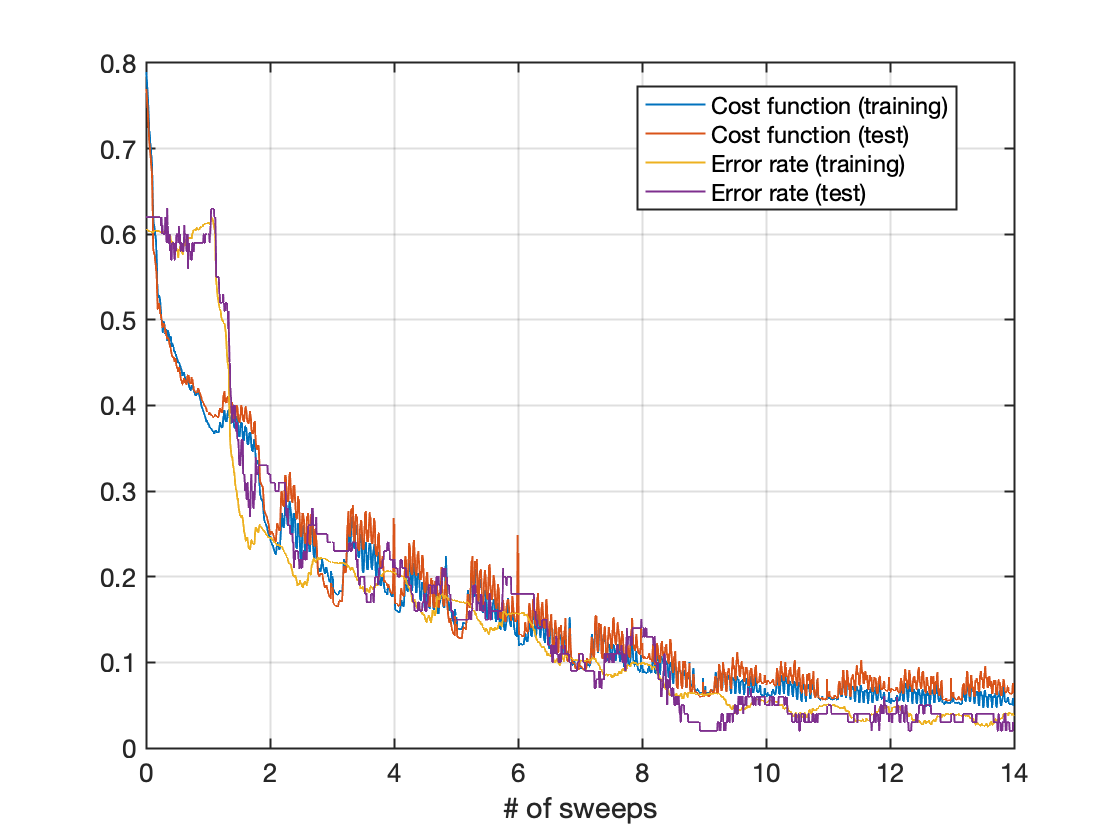

figure;
plot((1:numel(cfun)).'/numel(M), ...
    [cfun(:),cfun_test(:),err(:),err_test(:)], ...
    'LineWidth',1,'LineStyle','-');
set(gca,'LineWidth',1,'FontSize',13,'YScale','linear');
legend({'Cost function (training)','Cost function (test)', ...
    'Error rate (training)','Error rate (test)'},'Location','best');
xlabel('# of sweeps')
grid on;

We get a classification error rate of 3%, comparable with the reported value of 2% for the bond dimension $N_\mathrm{keep} = 20$ (see Sec. 5 of Stoudenmire2016). The classification error rate can be further improved by tuning `estep`, increasing `Nkeep`, or training more datasets.

Let's see some example for which the final MPS fails to classify data correctly.

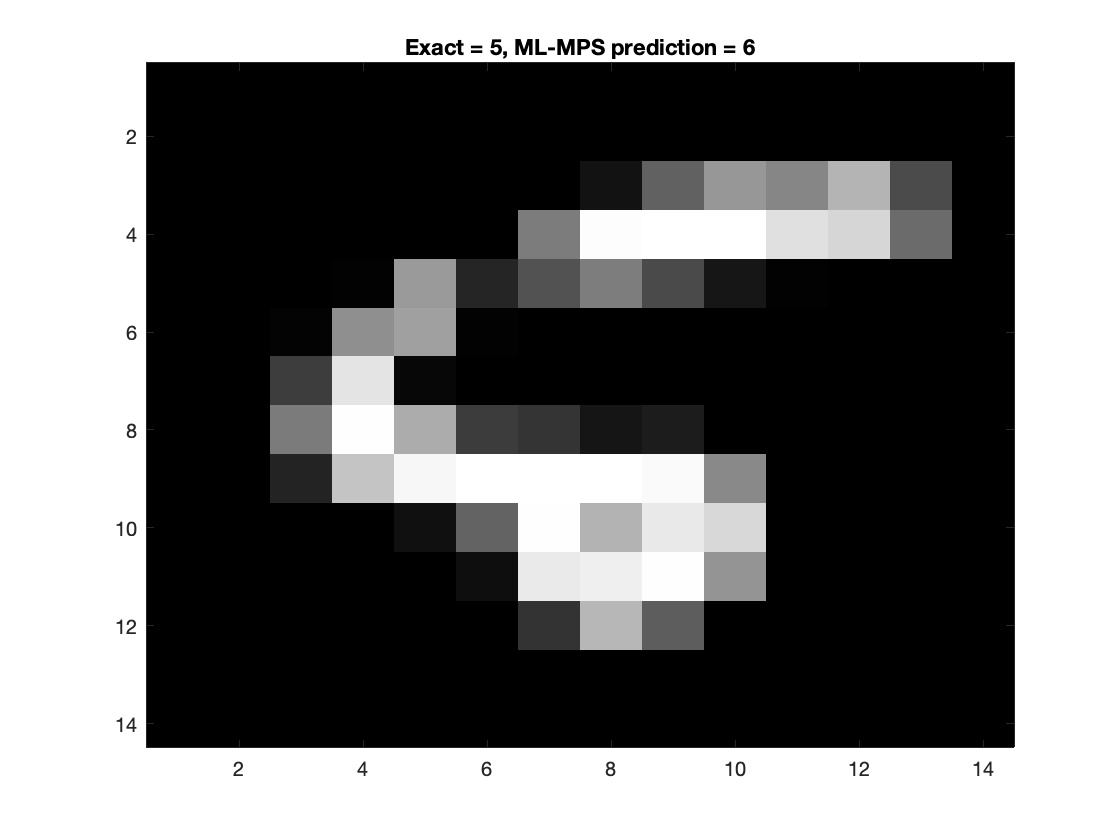

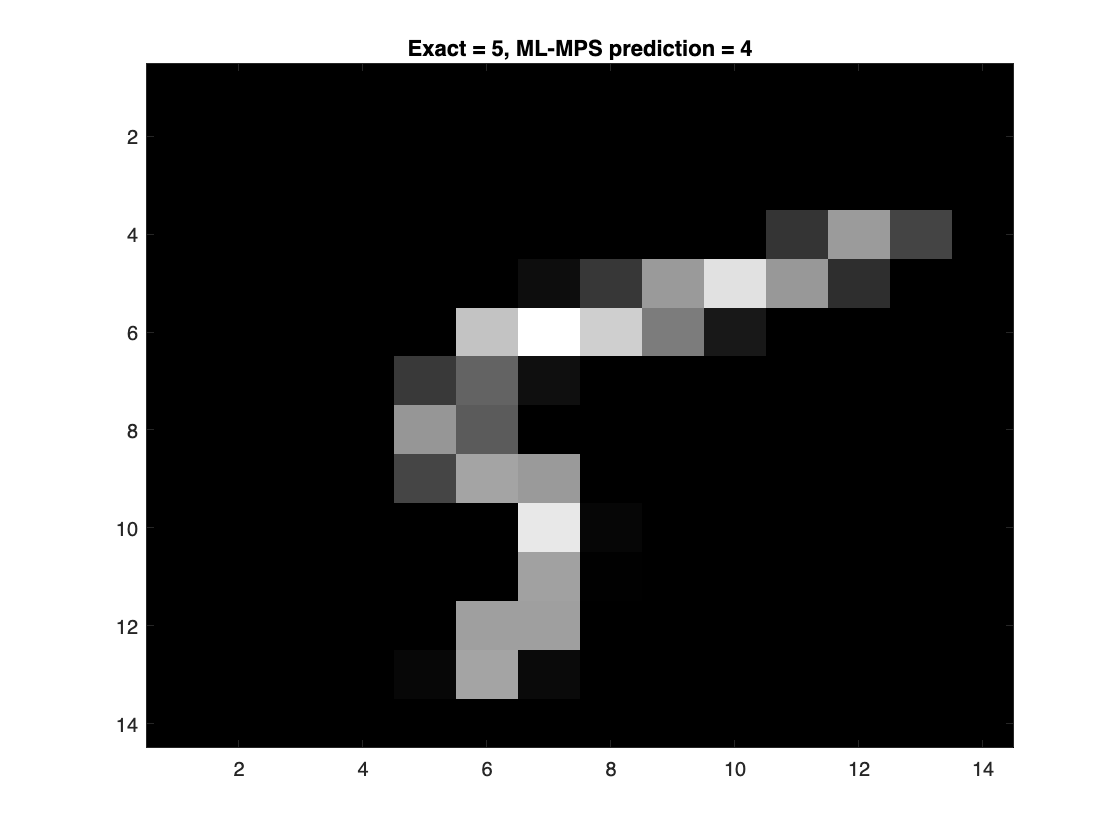

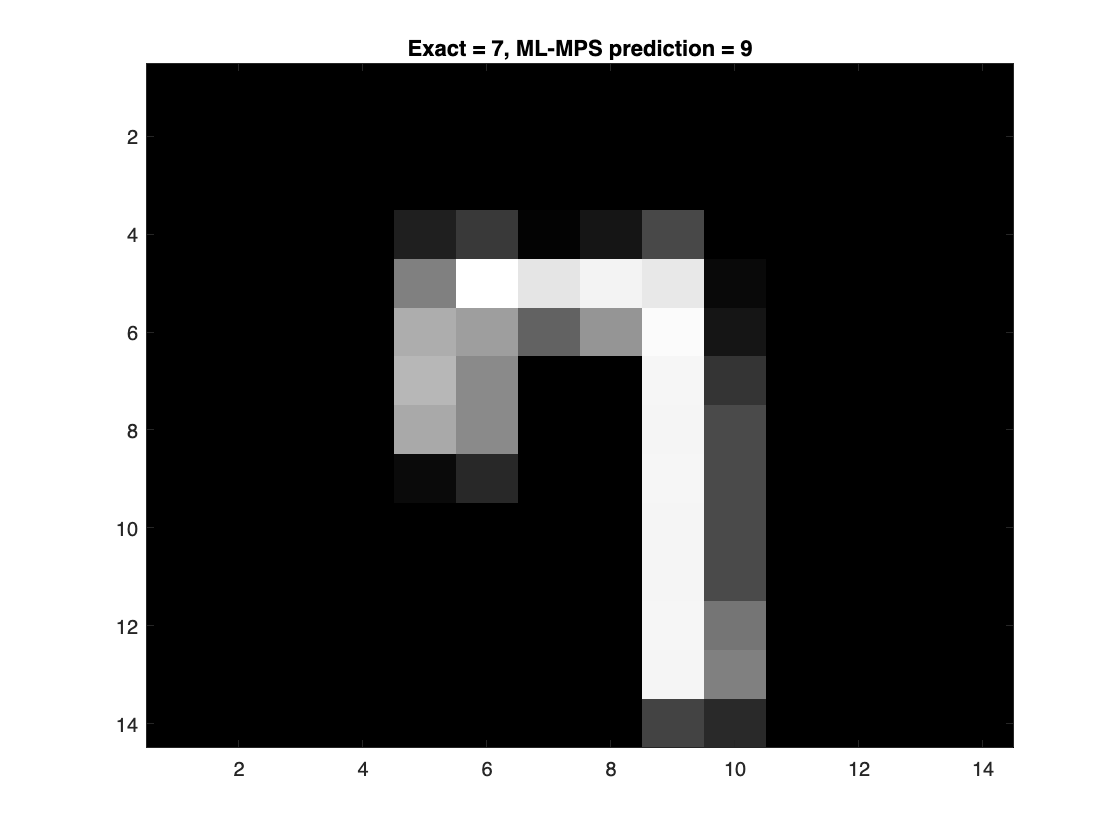

ids = find((lid_test-1) ~= data_test(:,1));
for itf = ids(:).'
    figure;
    imagesc(reshape(data_test(itf,2:end),(Npixel/2)*[1 1]).');
    colormap(gray);
    title(['Exact = ',sprintf('%i',data_test(itf,1)), ...
        ', ML-MPS prediction = ',sprintf('%i',lid_test(itf)-1)]);
end

You see that the ML-MPS code was not entirely wrong, as it found "similar" numbers in terms of their shapes!